# Создание матрицы

## Комментарии к старому подходу индексов спектра

Количество отчетов 

Samples_num = 1024;

Количество вырезок (cut) сигнала длинной в "Samples_num"

cuts = floor( length(z) / Samples_num ) - 1;

Коєффициент интерполяции для получения шага частоты df ~ 1Hz

k_interp = Fs/Samples_num - 1;

Массив нулей что должен быть добавлен к вырезанному сигналу для интерполяции спектра

zeros_num = floor(k_interp*Samples_num);
Zer = zeros(zeros_num, 1);

Определение индексов в интерполированном спектре для каждой ноты

L2 = ( (k_interp+1)*Samples_num);
Indexes = floor(L2 * Tab_F / Fs + 1);

Массив классификатор в котоорый будут помещены ноты что определены из каждого вырезанного куска сигнала

notes_lin = zeros(1, cuts);

## Создаем новый подход к матрице индексов

Идея - Создаем матрицу 10х84, где 84 - уникальные ноты, а 10 - индексы их гармоник или кратных частот в спектре длинной в 1024 семпла с учетом интерполяции с коэффициентом k_interp (примерно = 42).

Берем таблицу частот нот 7х12 и делаем из нее вектор 1х84 из возрастающих частот нот

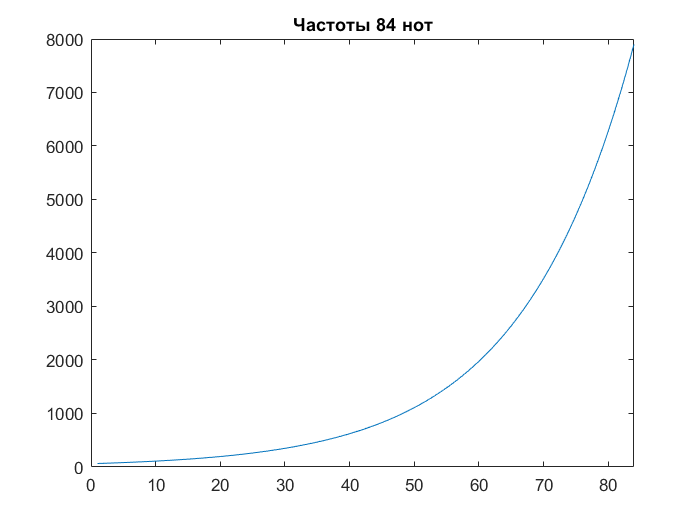

clear all
close all
Tab_F_1 = [65.41  69.3  73.42  77.78  82.41  87.31  92.5  98  103.83  110  116.54  123.47];

k = 2.^(0:6);
Tab_F = k' * Tab_F_1;
FlatTab_F = reshape(Tab_F.',1,[]);  % 1x84 частоты нот

figure
plot(FlatTab_F)
title("Частоты 84 нот")
xlim([0 84])

Создаем матрицу A [10х84], где каждой ноте будет соответствовать 10 кратных частот

v = 1:10;
A = v' * FlatTab_F;

Определяем кол-во отчетов спектра после интерполяции. В нашем частном случае, если мы хотим получить df = 1Hz, то кол-во отчетов равно частоте дискретизации 44100.

Samples_num = 1024;
Fs = 44100;
k_interp = Fs/Samples_num - 1;
zeros_num = floor(k_interp*Samples_num);

Notes_vector =         3593        3807        4033        4273        4528        4797        5085        5390        5705        6050        6405        6785        7190        7619        8071        8551        9060        9599       10175       10780       11415       12100       12815       13575       14385       15242       16148       17107       18125       19203       20350       21560       22837       24200       25634       27158       28775       30488       32300       34218       36255       38410       40700       43120       45680       48400       51272       54322       57556       60980



Total_Samples = Samples_num + zeros_num;

Находим индексы соответствующий частот матрицы А в интерполированном спектре. В нашем частном случае округленная частота и будет индексом.

A_ind = floor(A);   % Тут не хватает ограничения <44100

После подставления индексов в спектр находим сумму для каждой ноты

% Подставляем в спектр
Notes_vector = sum(A_ind);

## Пример подсчета с использованием нового метода

Загружаем сигнал для анализа

clear all
close all
path = 'D:\Desktop\Studie\Diploma\Audio data\wav\60 нот.wav';
[y, Fs] = audioread(path);
z = y(:,1);
clear y

Добавляем необходимые параметры для интерполяции

Samples_num = 1024;
k_interp = Fs/Samples_num - 1;
zeros_num = floor(k_interp*Samples_num);
Zer = zeros(zeros_num, 1);

Создаем матрицу индексов по новому методу

Tab_F_1 = [65.41  69.3  73.42  77.78  82.41  87.31  92.5  98  103.83  110  116.54  123.47];
k = 2.^(0:6);
Tab_F = k' * Tab_F_1;
FlatTab_F = reshape(Tab_F.',1,[]);
v = 1:10;
A = v' * FlatTab_F;
A_ind = floor(A);

A_ind(A_ind>15000) = 15000;     % Если мы выходим за границы частот
                                % Пусть это место будет 15кГц, там
                                % Мало интенсивности звука

FlatA_ind = reshape(A_ind.',1,[]);

Берем 2 заранее известных участка. i - номер вырезки по 1024 отчета

i = 80, До большой октавы (нота 1, октава 1)

i = 80;

n1 = i*Samples_num;         % Находим пределы сигнала для вырезки
n2 = (i+1)*Samples_num - 1;

S = z(n1: n2);        % Берем участок сигнала
S2 = vertcat (Zer, S);      % Интерполируем спектр
Spec = abs(fft(S2));        % Находим спектр сигнала

Notes_matrix = Spec(A_ind);
Notes_vector = sum(Notes_matrix)

Notes_vector =     0.4102    0.4653    0.4103    0.3713    0.4011    0.2659    0.3106    0.3801    0.2257    0.2996    0.2596    0.2828    0.1662    0.1619    0.1808    0.1461    0.2110    0.1141    0.1460    0.1734    0.1519    0.1804    0.1482    0.1930    0.0541    0.0887    0.1184    0.0743    0.1343    0.0932    0.1055    0.1005    0.0971    0.0926    0.1040    0.1344    0.0479    0.0564    0.0456    0.0629    0.0776    0.0445    0.0594    0.0450    0.0414    0.0556    0.0428    0.0460    0.0273    0.0325


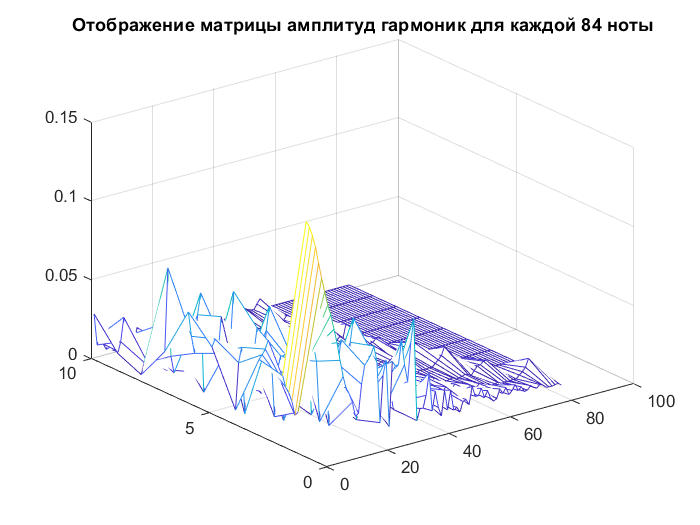


figure
mesh(Notes_matrix)
title("Отображение матрицы амплитуд гармоник для каждой 84 ноты")

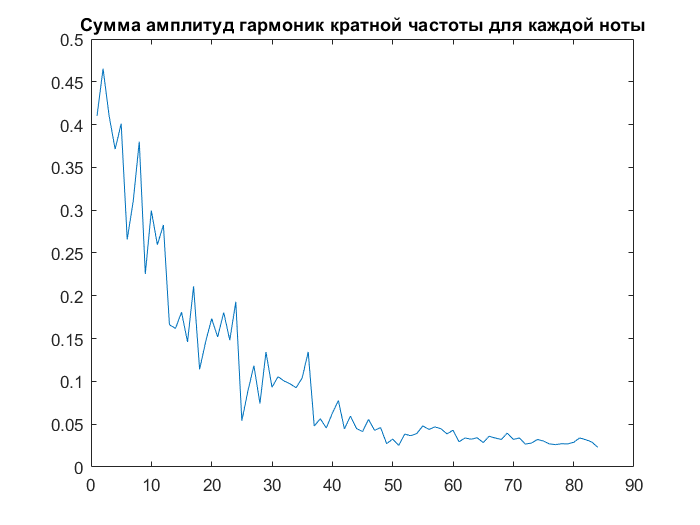


figure
plot(Notes_vector)
title("Сумма амплитуд гармоник кратной частоты для каждой ноты")

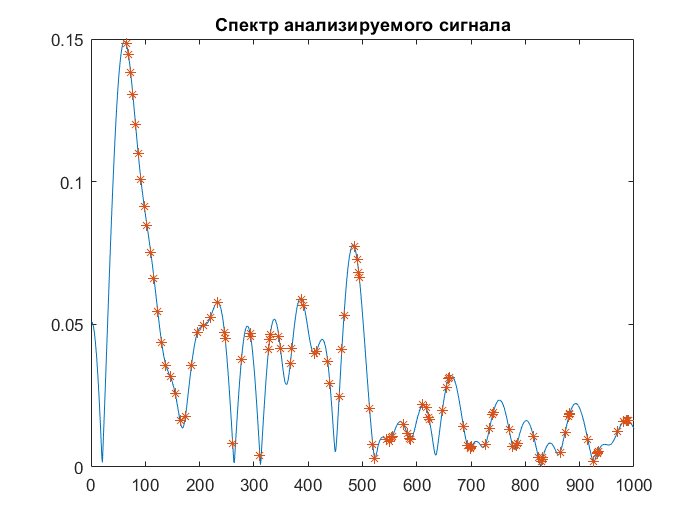


figure
plot(Spec)
hold on
plot(FlatA_ind, Spec(FlatA_ind),  '*')
xlim([0 1000])
title("Спектр анализируемого сигнала")

И второй заранее известный случай

i=1550, Си 3 октавы с гармоникой на 4той октаве выше по амплитуде

i = 1550;

n1 = i*Samples_num;         % Находим пределы сигнала для вырезки
n2 = (i+1)*Samples_num - 1;

S = z(n1: n2);        % Берем участок сигнала
S2 = vertcat (Zer, S);      % Интерполируем спектр
Spec = abs(fft(S2));        % Находим спектр сигнала

Notes_matrix = Spec(A_ind);
Notes_vector = sum(Notes_matrix)

Notes_vector =     4.8034    7.0022    6.5957    4.1773    6.3530    5.6891    4.4841   12.2114    5.9151    9.2661    5.1388   11.1679    5.8652    6.3463    6.1986    4.8776   13.6595    5.3613    5.5804    7.0953    2.1096    3.6219    3.8076   13.1714    4.2813    2.5812    3.8600    2.3628    6.3725    2.2702    3.2560    1.7534    1.1640    2.1863    3.0986   12.5821    3.5262    1.5614    1.0417    0.6179    0.9203    0.7094    2.7229    0.5097    0.6187    0.8269    1.2452    5.4918    1.1136    0.5114


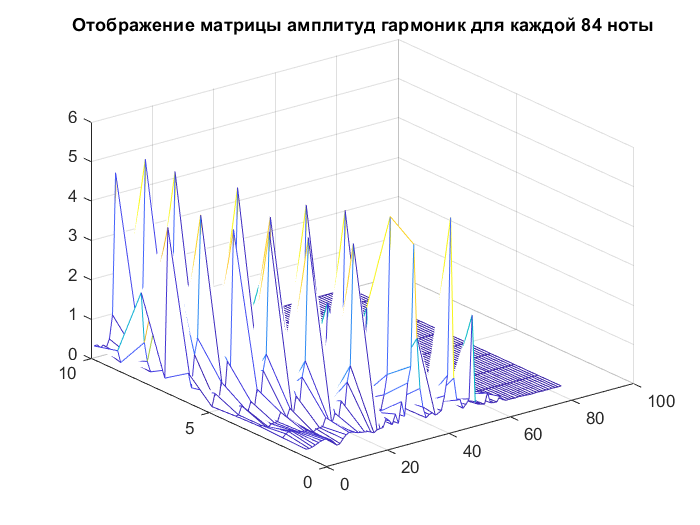


figure
mesh(Notes_matrix)
title("Отображение матрицы амплитуд гармоник для каждой 84 ноты")

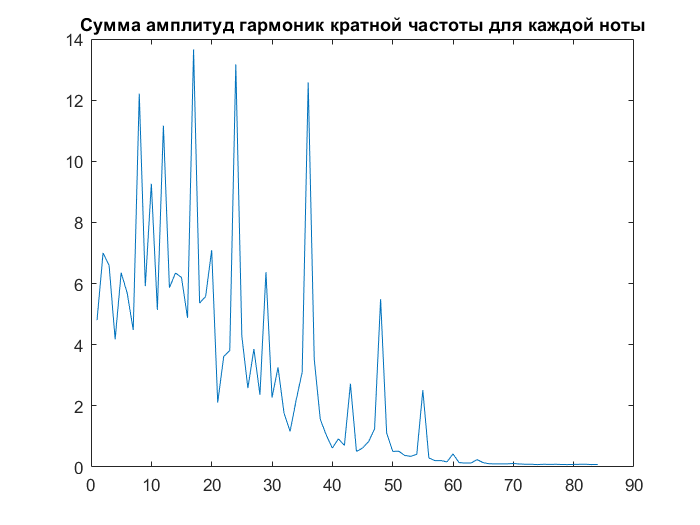


figure
plot(Notes_vector)
title("Сумма амплитуд гармоник кратной частоты для каждой ноты")

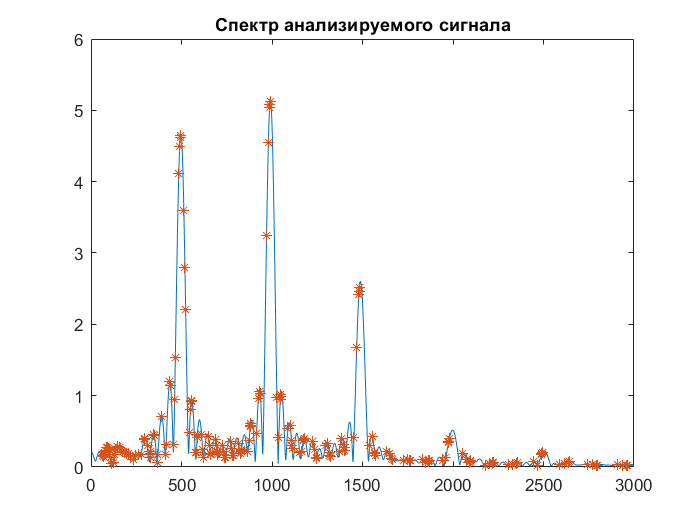


figure
plot(Spec)
hold on
plot(FlatA_ind, Spec(FlatA_ind),  '*')
xlim([0 3000])
title("Спектр анализируемого сигнала")